k = P1D.Kp;   %Ts = 0.897s
tau = P1D.Tp1;
motor_tf = tf(k,[tau,1]);
[A B C D] = tf2ss(k,[tau,1]);
motor_ss = ss(A,B,C,D)


motor_ss =
 
  A = 
           x1
   x1  -4.363
 
  B = 
       u1
   x1   1
 
  C = 
          x1
   y1  366.7
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


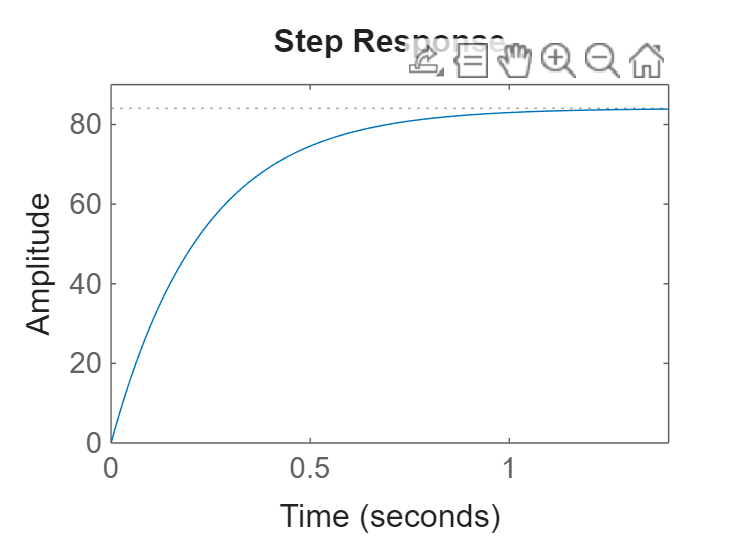

step(motor_ss)

%checking controllability of states
cm = ctrb(A,B) % gives the controllability matrix

cm = 1

c = rank(cm)

c = 1

%desired characteristics Ts = 0.5s
Jc = -8

Jc = -8

k = place(A,B,Jc)

k = 3.6374

Acl = A - B*k;
eig(Acl)  % checked closed loop poles of controller

ans = -8

% Compute feedforward Ko for unity step steady-state
% For regulator with u = Ko*r - K x and r is stepx`
Koc = -1 / (C * (Acl \ B))

Koc = 0.0218

%continuous plant works so lets discretize it
T = 0.001

T = 1.0000e-03

[G H] = c2d(A,B,T)

G = 0.9956

H = 9.9782e-04

sys_ss_d = ss(G,H,C,D,T)


sys_ss_d =
 
  A = 
           x1
   x1  0.9956
 
  B = 
              u1
   x1  0.0009978
 
  C = 
          x1
   y1  366.7
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.
Model Prop

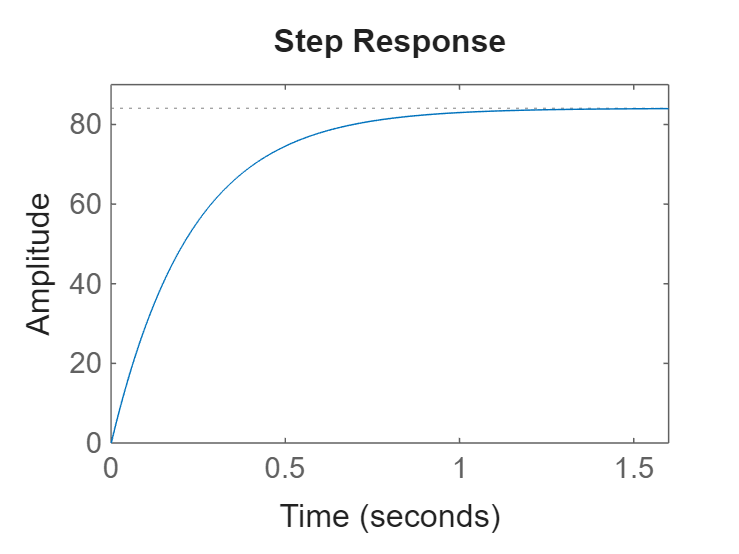

step(sys_ss_d)

%checking controllability of states
cm_d = ctrb(G,H) % gives the controllability matrix

cm_d = 9.9782e-04

c_d = rank(cm_d)

c_d = 1

%desired characteristics Ts = 4s M% = 5%
Jd = exp(Jc*T)

Jd = 0.9920

k_d = place(G,H,Jd)

k_d = 3.6228

Acl_d = G - H*k_d;
eig(Acl_d)  % checked closed loop poles of controller

ans = 0.9920

% Compute feedforward Ko for unity step steady-state
% For regulator with u = Ko*r - K x and r is stepx`
I = eye(size(Acl_d));
Kod = 1 / ( C * ( (I - Acl_d) \ H ) )

Kod = 0.0218